clc
clear

**Zapisanie wygenerowanego sygnału do pliku .mat** (uzupełnić ścieżkę):

lokalizacja = "C:\...\ofdm.mat";
m = matfile(lokalizacja, "Writable", true);

## I. Zdefiniowanie sygnału

**1.**  **Wybór jednego z dostępnych kanałów:** 

{'NOF1', 'NCS1', 'BCH1', 'KAU1', 'KAU2'}.

channel = 'BCH1';

**2.** **Zdefiniowanie pasma częstotliwości i odpowiedniej częstotliwości próbkowania fs_x:**

switch channel
    case {'NOF1', 'NCS1'}
        f_min = 10000; 
        f_max = 18000;
        fs_x  = 38400;  % Podzielne przez 2^n.
    case 'BCH1'
        f_min = 32500; 
        f_max = 37500;
        fs_x  = 76800;  % Podzielne przez 2^n.
    case {'KAU1', 'KAU2'}
        f_min = 4000; 
        f_max = 8000;
        fs_x  = 19200;  % Podzielne przez 2^n.
    otherwise
        error('Invalid channel selected');
end

Nie wolno zmieniać częstotliwości minimalnych ani maksymalnych (są one narzucone przez twórców oprogramowania), można natomiast dostosować częstotliwość próbkowania, pamiętając o spełnieniu **twierdzenia Nyqusita** (**Shannona-Kotielnikowa**).

**3. Pozostałe parametry:**

**a) Liczba podnośnych sygnału OFDM:**

N = 128;

Każda z podnośnych przenosi część wiadomości. 

N = 2^7 = 128 zmniejsza odstęp między podnośnymi, co redukuje ISI (Inter-Symbol Interference) ale zwiększa wrażliwość na efekt Dopplera.

**b)  Długość prefiksu cyklicznego:**

cp_len = N/4;

Prefiks cykliczny dodaje redundancję w celu przeciwdziałania zjawisku echa (wielodrożności) w wodzie.

Cp_len = N/4 zapewnia dobrą ochronę przed wielodrożnością w akustyce podwodnej.

**c) Czas trwania sygnału** (dostosować w razie potrzeby):

T = 5; % [s]

**d) Wektor czasu:**

t = (0:1/fs_x:T-1/fs_x);

## II. Modulacja sygnału

1. **Wybór modulacji**

Dla Sygnałów OFDM rekomendowane są następujące modulacje:

{'BPSK", 'QPSK', '16-AM'}

modulation = 'QPSK';

Liczba bitów na poszczególny symbol (**nie zmieniać!**):

switch modulation
    case {'BPSK'}
        M = 2;      % 1 bit na symbol
    case {'QPSK'}
        M = 4;      % 2 bity na symbol
    case '16-AM'
        M = 16;     % 4 bity na symbol
    otherwise
        error('Invalid modulation selected');
end

**1 bit na symbol** cechuje się dużą odpornaością na zakłócenia, kosztem niskiej przepływności danych;

**2 bity na symbol** zapewniają równowagę między przepływnością i odpornością danych;

**4 bity na symbol** wiążą się z większą przepływnością, ale mniejszą odpornością danych.

**2. Obliczanie liczby bitów (****nie zmieniać!****)**

**a) Liczba bitów na symbol OFDM:**

bps = N*log2(M);                                               

**b) Liczba symboli na sekundę:**

symbol_rate = fs_x/N;

**c) Całkowita liczba bitów w czasie T ** (z uwzględnieniem prefiksu cyklicznego):

nBits = T*(symbol_rate*bps*N/(N + cp_len));

## III. Generowanie strumienia bitów

**1. Losowy ciąg bitów** (symuluje rzeczywiste dane):

data_bits = randi([0 1], nBits, 1);

**2. Weryfikacja czy liczba bitów pasuje dokładnie do liczby symboli**

**a) Całkowita liczba symboli:**

num_symbols = floor(nBits/log2(M));

b) **Przycinanie nadmiarowych bitów (**w razie konieczności):

data_bits = data_bits(1:num_symbols*log2(M));

**3. Przekształcenie na porcje odpowiadające jednemu symbolowi **(Przekształcenie do formy odpowiedniej do modulacji)**:**

data_symbols = reshape(data_bits, [], log2(M));

## IV. Parametry modulacji

**1. Zaaplikowanie modulacji**

switch M %
    case 2 % **BPSK**
        modulated_symbols = 2*data_symbols - 1;
    case 4  % **QPSK**
        modulated_symbols = (2*data_symbols(:,1) - 1) + ...
                            1j*(2*data_symbols(:,2) - 1);    
    case 16  % **16-QAM**
        decimal_values = bi2de(data_symbols);  % Zamiana bitów na liczby dziesiętne
        modulated_symbols = qammod(decimal_values, 16, 'UnitAveragePower', true);
    otherwise
        error('Unsupported modulation scheme');
end

**BPSK:** mapuje 0 → -1 i 1 → +1;

**QPSK:** pary bitów są mapowane na wartości zespolone (składowa I i Q);

**16-QAM**: grupy po 4 bity są mapowane na konstelację punktów.

**2.Weryfikacja czy długość jest podzielna przez liczbę podnośnych N**

**a) Dopasowanie długości do wielokrotności N**

num_symbols_adjusted = floor(length(modulated_symbols)/N)*N;

**b) Przycięcie nadmiarowych symboli w razie potrzeby**

modulated_symbols_adjusted = modulated_symbols(1:num_symbols_adjusted);

## V. Konstrukcja sygnału OFDM

**1. Przekształcenie zmodulowanych symboli do ramki OFDM** (N podnośnych na symbol)

ofdm_frame = reshape(modulated_symbols_adjusted, N, []);   % Automatyczne dopasowanie liczby symboli

**2. Zastosowanie odwrotnej transformacji Fouriera **(IFFT)** na każdej kolumnie ramki OFDM**

ofdm_time_domain = ifft(ofdm_frame, N, 1);  % IFFT wzdłuż kolumn

**3. Dodanie prefiksu cyklicznego **(CP)

ofdm_time_domain_cp = [ofdm_time_domain(end-cp_len+1:end, :); ofdm_time_domain];

**4. Przekształcenie symbolu w dziedzinie czasu do pojedynczego wektora sygnału x**

x = reshape(ofdm_time_domain_cp, [], 1)';  % Konwersja do pojedynczego wektora (wiersza)

## 6. Eksport sygnału

(Zapis do pliku .mat):

m.x = x;
m.fs_x = fs_x;
m.nBits = nBits;  

disp(['Selected channel: ', channel]);
disp(['Selected sampling rate: ', num2str(fs_x), ' Hz']);
disp(['Selected number of information bits: ', num2str(nBits)]);
disp(['Length of the signal x: ', num2str(length(x))]);

## Treści dodatkowe:

(zakomentować, jeśli niepotrzebne):

**1. Sprawdzenie poprawności działania skryptu**

disp(['Channel: ', channel]);

Channel: BCH1


disp(['Sampling Rate: ', num2str(fs_x), ' Hz']);

Sampling Rate: 76800 Hz


disp(['Modulation: ', modulation]);

Modulation: QPSK


disp(['Total Bits: ', num2str(nBits)]);

Total Bits: 614400


disp(['OFDM Symbols: ', num2str(num_symbols)]);

OFDM Symbols: 307200


disp(['Length of the signal x: ', num2str(length(x))]);

Length of the signal x: 384000


disp('OFDM data symbols generated successfully!');

OFDM data symbols generated successfully!


**2. Przebieg sygnału w czasie**

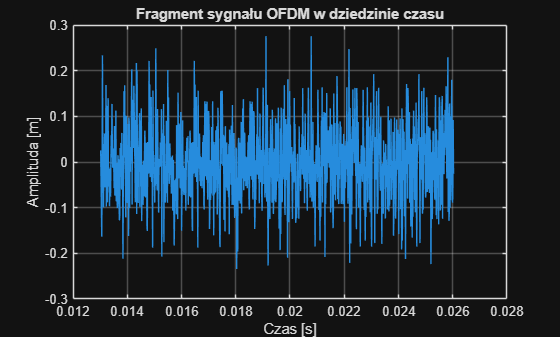

figure;
plot(t(1001:2000), real(x(1001:2000))); % Część rzeczywista sygnału
title('Fragment sygnału OFDM w dziedzinie czasu');
xlabel('Czas [s]');
ylabel('Amplituda [m]');
grid on

**3. Widmo amplitudowo-częstotliwościowe**

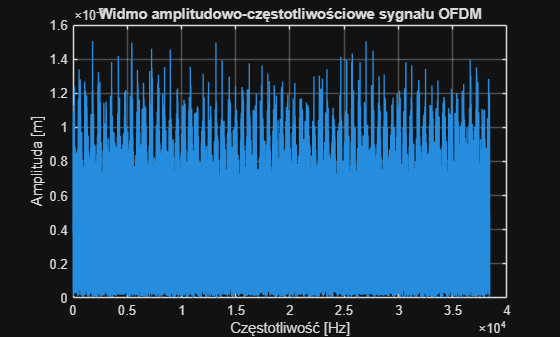

n = length(x);
y = abs(fft(x)/(n/2));
f = fs_x*(0:n/2-1)/n;
y = y(1:n/2);
x = x(:);

figure;
plot(f, real(y));
title('Widmo amplitudowo-częstotliwościowe sygnału OFDM');
xlabel('Częstotliwość [Hz]');
ylabel('Amplituda [m]');
grid on;